# Train DDPG Agent for Adaptive Cruise Control

This example shows how to train a deep deterministic policy gradient (DDPG) agent for adaptive cruise control (ACC) in Simulink®. For more information on DDPG agents, see [Deep Deterministic Policy Gradient Agents](docid:rl_ug#mw_66c8fe60-f58e-4bdb-904a-21d442f0a879).

## Simulink Model

The reinforcement learning environment for this example is the simple longitudinal dynamics for an ego car and lead car. The training goal is to make the ego car travel at a set velocity while maintaining a safe distance from lead car by controlling longitudinal acceleration and braking. This example uses the same vehicle model as the [Adaptive Cruise Control System Using Model Predictive Control](docid:mpc_ug#mw_5d3362c7-033d-4773-a8e5-5f3d303a9c10) example.

Specify the initial position and velocity for the two vehicles.

x0_lead = 50;   % initial position for lead car (m)
v0_lead = 25;   % initial velocity for lead car (m/s)
x0_ego = 10;    % initial position for ego car (m)
v0_ego = 20;    % initial velocity for ego car (m/s)

Specify standstill default spacing (m), time gap (s) and driver-set velocity (m/s).

D_default = 10;
t_gap = 1.4;
v_set = 30;

To simulate the physical limitations of the vehicle dynamics, constraint the acceleration to the range `[–3,2]` m/s^2.

amin_ego = -3;
amax_ego = 2;

Define the sample time `Ts` and simulation duration `Tf` in seconds.

Ts = 0.1;
Tf = 60;

Open the model.

mdl = 'rlACCMdl';
open_system(mdl)
agentblk = [mdl '/RL Agent'];

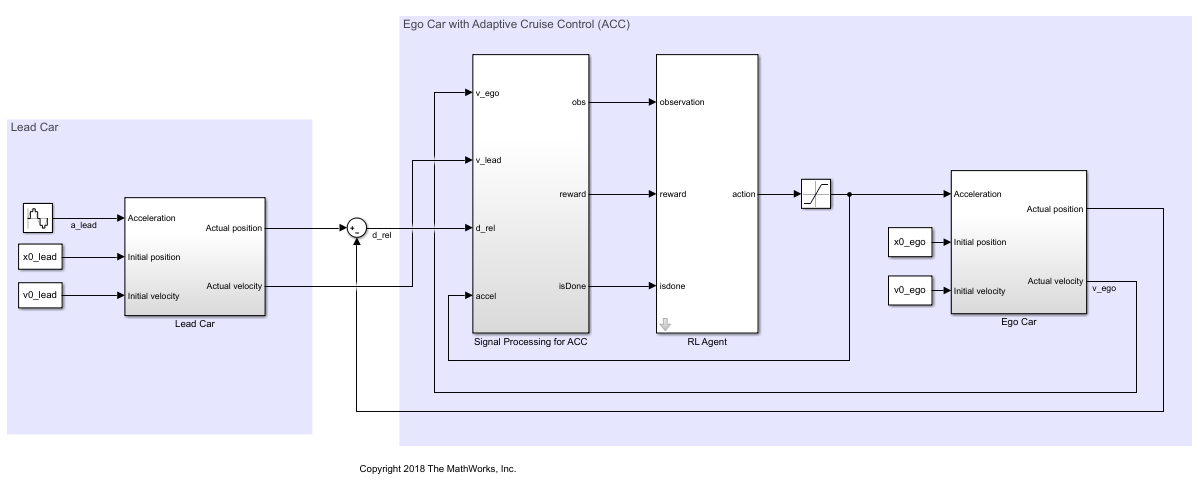

For this model:

- The acceleration action signal from the agent to the environment is from –3 to 2 m/s^2.

- The reference velocity for the ego car $V_{ref}$ is defined as follows. If the relative distance is less than the safe distance, the ego car tracks the minimum of the lead car velocity and driver-set velocity. In this manner, the ego car maintains some distance from the lead car. If the relative distance is greater than the safe distance, the ego car tracks the driver-set velocity. In this example, the safe distance is defined as a linear function of the ego car longitudinal velocity $V$; that is, $t_{gap}*V+D_{default}$. The safe distance determines the reference tracking velocity for the ego car.

- The observations from the environment are the velocity error $e = V_{ref}-V_{ego}$, its integral $\int e$, and the ego car longitudinal velocity $V$. 

- The simulation is terminated when longitudinal velocity of the ego car is less than 0, or the relative distance between the lead car and ego car becomes less than 0.

- The reward $r_t$, provided at every time step $t$, is


$$r_t = -(0.1e_t^2+u_{t-1}^2)+M_t
$$


              where $u_{t-1}$ is the control input from the previous time step. The logical value $$M_t = 1$$ if velocity error $$e_t^2<=0.25$$; otherwise, $$M_t = 0$$.

## Create Environment Interface

Create a reinforcement learning environment interface for the model.

Create the observation specification.

observationInfo = rlNumericSpec([3 1],'LowerLimit',-inf*ones(3,1),'UpperLimit',inf*ones(3,1));
observationInfo.Name = 'observations';
observationInfo.Description = 'information on velocity error and ego velocity';

Create the action specification.

actionInfo = rlNumericSpec([1 1],'LowerLimit',-3,'UpperLimit',2);
actionInfo.Name = 'acceleration';

Create the environment interface.

env = rlSimulinkEnv(mdl,agentblk,observationInfo,actionInfo);

To define the initial condition for the position of the lead car, specify an environment reset function using an anonymous function handle. The reset function `localResetFcn`, which is defined at the end of the example, randomizes the initial position of the lead car.

env.ResetFcn = @(in)localResetFcn(in);

Fix the random generator seed for reproducibility.

rng('default')

## Create DDPG agent

A DDPG agent approximates the long-term reward given observations and actions using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the state and action, and one output. For more information on creating a neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

L = 48; % number of neurons
statePath = [
    featureInputLayer(3,'Normalization','none','Name','observation')
    fullyConnectedLayer(L,'Name','fc1')
    reluLayer('Name','relu1')
    fullyConnectedLayer(L,'Name','fc2')
    additionLayer(2,'Name','add')
    reluLayer('Name','relu2')
    fullyConnectedLayer(L,'Name','fc3')
    reluLayer('Name','relu3')
    fullyConnectedLayer(1,'Name','fc4')];

actionPath = [
    featureInputLayer(1,'Normalization','none','Name','action')
    fullyConnectedLayer(L, 'Name', 'fc5')];

criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork, actionPath);
    
criticNetwork = connectLayers(criticNetwork,'fc5','add/in2');

View the critic network configuration.

plot(criticNetwork)

Specify options for the critic representation using [`rlRepresentationOptions`](docid:rl_ref#mw_45ccf57d-64f0-4822-8000-3f0f44f2572e).

criticOptions = rlRepresentationOptions('LearnRate',1e-3,'GradientThreshold',1,'L2RegularizationFactor',1e-4);

Create the critic representation using the specified neural network and options. You must also specify the action and observation info for the critic, which you obtain from the environment interface. For more information, see [`rlQValueRepresentation`](docid:rl_ref#mw_6e9cf856-c679-4834-97e1-1349c4a21e43).

critic = rlQValueRepresentation(criticNetwork,observationInfo,actionInfo,...
    'Observation',{'observation'},'Action',{'action'},criticOptions);

A DDPG agent decides which action to take given observations by using an actor representation. To create the actor, first create a deep neural network with one input, the observation, and one output, the action.

Construct the actor similarly to the critic. For more information, see [`rlDeterministicActorRepresentation`](docid:rl_ref#mw_425a8728-2966-45c4-9d2a-488aa4a506bf).

actorNetwork = [
    featureInputLayer(3,'Normalization','none','Name','observation')
    fullyConnectedLayer(L,'Name','fc1')
    reluLayer('Name','relu1')
    fullyConnectedLayer(L,'Name','fc2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(L,'Name','fc3')
    reluLayer('Name','relu3')
    fullyConnectedLayer(1,'Name','fc4')
    tanhLayer('Name','tanh1')
    scalingLayer('Name','ActorScaling1','Scale',2.5,'Bias',-0.5)];

actorOptions = rlRepresentationOptions('LearnRate',1e-4,'GradientThreshold',1,'L2RegularizationFactor',1e-4);
actor = rlDeterministicActorRepresentation(actorNetwork,observationInfo,actionInfo,...
    'Observation',{'observation'},'Action',{'ActorScaling1'},actorOptions);

To create the DDPG agent, first specify the DDPG agent options using [`rlDDPGAgentOptions`](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c).

agentOptions = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'ExperienceBufferLength',1e6,...
    'DiscountFactor',0.99,...
    'MiniBatchSize',64);
agentOptions.NoiseOptions.Variance = 0.6;
agentOptions.NoiseOptions.VarianceDecayRate = 1e-5;

Then, create the DDPG agent using the specified actor representation, critic representation, and agent options. For more information, see [rlDDPGAgent](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef).

agent = rlDDPGAgent(actor,critic,agentOptions);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run each training episode for at most `5000` episodes, with each episode lasting at most 600 time steps.

- Display the training progress in the Episode Manager dialog box.

- Stop training when the agent receives an episode reward greater than 260. 

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxepisodes = 5000;
maxsteps = ceil(Tf/Ts);
trainingOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes,...
    'MaxStepsPerEpisode',maxsteps,...
    'Verbose',false,...
    'Plots','training-progress',...
    'StopTrainingCriteria','EpisodeReward',...
    'StopTrainingValue',260);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = false;

if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainingOpts);
else
    % Load a pretrained agent for the example.
    load('SimulinkACCDDPG.mat','agent')       
end

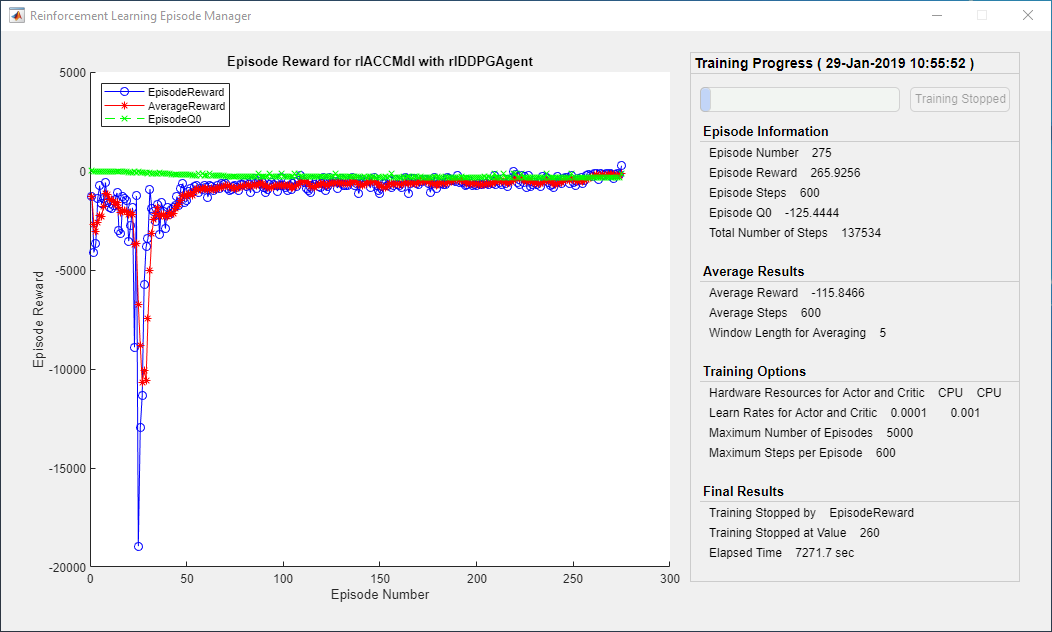

## Simulate DDPG Agent

To validate the performance of the trained agent, simulate the agent within the Simulink environment by uncommenting the following commands. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

% simOptions = rlSimulationOptions('MaxSteps',maxsteps);
% experience = sim(env,agent,simOptions);

To demonstrate the trained agent using deterministic initial conditions, simulate the model in Simulink. 

x0_lead = 80;
sim(mdl)

The following plots show the simulation results when lead car is 70 (m) ahead of the ego car. 

- In the first 28 seconds, the relative distance is greater than the safe distance (bottom plot), so the ego car tracks set velocity (middle plot). To speed up and reach the set velocity, acceleration is positive (top plot). 

- From 28 to 60 seconds, the relative distance is less than the safe distance (bottom plot), so the ego car tracks the minimum of the lead velocity and set velocity. From 28 to 36 seconds, the lead velocity is less than the set velocity (middle plot). To slow down and track the lead car velocity, acceleration is negative (top plot). From 36 to 60 seconds, the ego car adjusts its acceleration to track the reference velocity closely (middle plot). Within this time interval, the ego car tracks the set velocity from 43 to 52 seconds and tracks lead velocity from 36 to 43 seconds and 52 to 60 seconds.

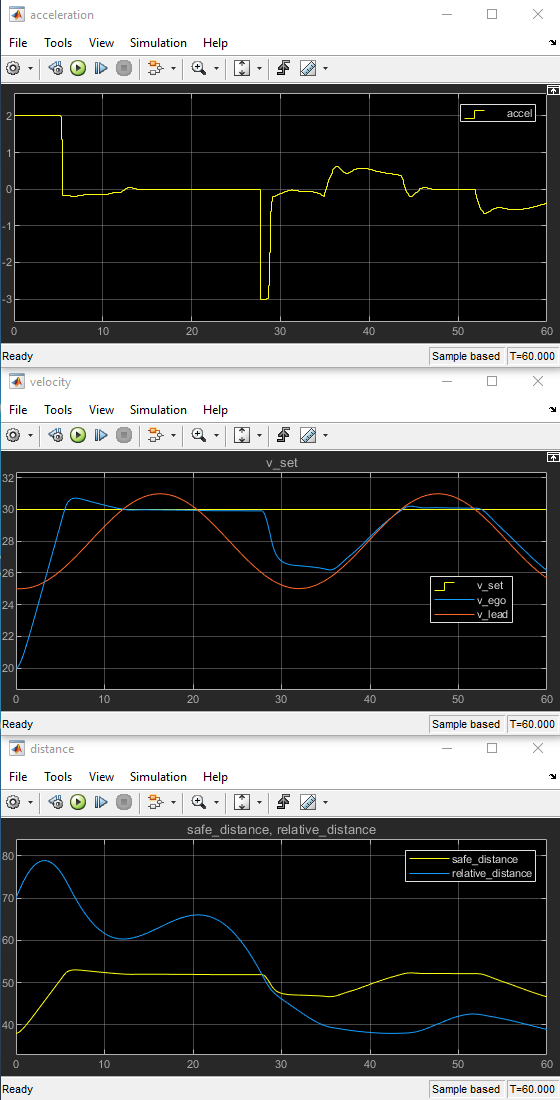

Close the Simulink model.

bdclose(mdl)

## Reset Function

function in = localResetFcn(in)
% Reset the initial position of the lead car.
in = setVariable(in,'x0_lead',40+randi(60,1,1));
end

*Copyright 2019 The MathWorks, Inc.*